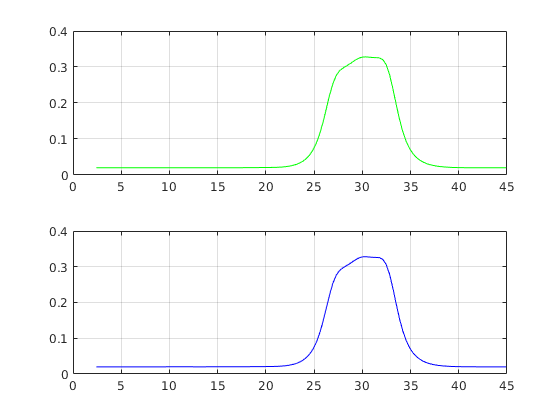

clear all
%{
%data loading
data_raw_1 = load('/home/abrar/Desktop/research/SEED Dataset/Subject 15/Pos/15-3-10pos.mat');
data_1 = data_raw_1.ch;

channel = 23;
raw_data_1 = data_1(channel,:);

%initial values
Length_1 = length(raw_data_1);

F_sample = 200;
F_nquist = F_sample/ 2;
T_sample = 1/F_sample;

time_series_1 = (0:Length_1-1)*T_sample;

%notch filtering
notch_filter_50_hz = designfilt('bandstopiir','FilterOrder',2,'HalfPowerFrequency1',48,'HalfPowerFrequency2',52, ...
    'DesignMethod','butter','SampleRate',200);

notch_filtered_sig_1 = filtfilt(notch_filter_50_hz,raw_data_1);

%band pass
bp_500_filter_4_40 = fir1(500, [8,40]/100, 'bandpass');

signal_1 = filter(bp_500_filter_4_40,1,notch_filtered_sig_1);

%p=6, th = 1.1
[music_p_th_signal_1_579, f_p_th_signal_1_579] = ...
    pmusic(signal_1, [6,1.1], 579, F_sample, 50, 25);

%selected 124 dft point band (2.4 hz to 45 hz)
calculated_signal = music_p_th_signal_1_579(8:131);
calculated_freq = f_p_th_signal_1_579(8:131);

%}


%automated

clear all

[extract_channels] = extract_channels_script;

[get_feature_matrix, get_welc_matrix, get_music_matrix] = spectrum_transformation_script;


file_name = "/home/abrar/Desktop/research/SEED Dataset/Subject 1/Neg/1-1-3neg.mat";
raw_data_matrix = read_file(file_name);

extracted_data_matrix= extract_channels(raw_data_matrix);

welch_matrix_extracted_channels = get_welc_matrix(extracted_data_matrix);
music_matrix_extracted_channels = get_music_matrix(extracted_data_matrix);

auto_1 = readtable('/home/abrar/Desktop/transformed_seed_extracted/music_dir/Subject 1/Neg/1-1-3neg_music.csv');

figure;
subplot(2,1,1)
plot(music_matrix_extracted_channels(:,1), music_matrix_extracted_channels(:,2), 'g')
grid on

subplot(2,1,2)
plot(auto_1.f,auto_1.ch_1,'b')
grid on


auto_2 = readtable('/home/abrar/Desktop/transformed_seed_extracted/welch_dir/Subject 1/Neg/1-1-3neg_welc.csv');

figure;
subplot(2,1,1)
plot(welch_matrix_extracted_channels(:,1), welch_matrix_extracted_channels(:,2), 'g')
grid on

subplot(2,1,2)
plot(auto_2.f,auto_2.ch_1,'b')
grid on



function raw_data_matrix_local = read_file(file_name)

    data_strc = load(file_name);
    raw_data_matrix_local = data_strc.ch;

end

